# Plots node pressure for a specific time.

### This function contains: 

- Load a network. 

- Hydraulic analysis using EN functions. 

- Plot pressure after d.plot. 

- Plot pressure only nodes. 

- Unload library.

### Clear - Start Too`lkit

clear; close('all'); clc;
start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


### Load a network.

inpname = 'net2.inp';
d = epanet(inpname);

EPANET version {20200} loaded (EMT version {v2.2.003}).
Loading File "net2.inp"...
Input File "net2.inp" loaded sucessfuly.


### Hydraulic analysis using EN functions.

values = d.getComputedHydraulicTimeSeries;
press = values.Pressure;
flow = values.Flow;
coords = d.getNodeCoordinates;

### 1. Plot pressure at hour 1

#### Show type of node

d.plot('legendposition', 'best')

ans =   Axes with properties:

             XLim: [6.5000 60.5000]
             YLim: [-4.3000 95.3000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


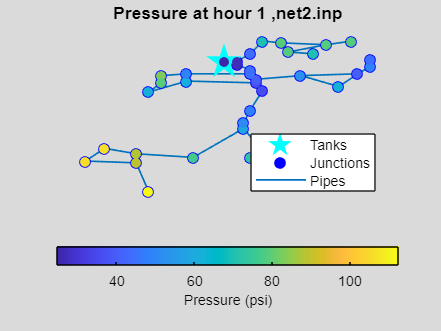

hold on
for i=1:length(press(1,:))
    scatter(coords{1}(i),coords{2}(i),35, press(1,i), 'filled')
end
title(['Pressure at hour 1 ,', inpname])
c = colorbar('southoutside');
c.Label.String = ['Pressure (', d.NodePressureUnits, ')'];

### 2.Plot pressure at hour 1 - 2

#### Hide type of node

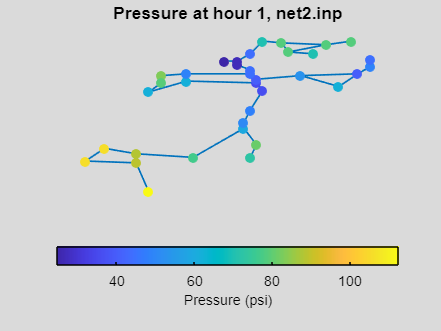

d.plot('point', 'no', 'legend', 'hide');
hold on
for i=1:length(press(1,:))
    scatter(coords{1}(i),coords{2}(i),35, press(1,i), 'filled')
end
title(['Pressure at hour 1, ', inpname])
c = colorbar('southoutside');
c.Label.String = ['Pressure (', d.NodePressureUnits, ')'];

### Unload library.

d.unload

EPANET Class is unloaded
